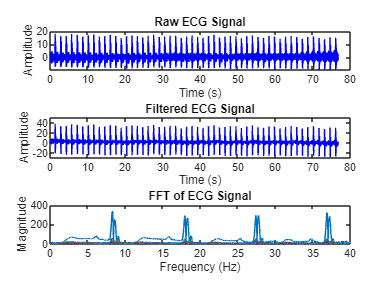


close all;
clear;
load('rect1.mat') 
ec=(val)/200;         %val is samples/signal.[(val-base)/gain] 
fs=500;    % Replace with your sampling frequency (in Hz)

% Plot the raw ECG signal
time = (0:length(ec)-1) / fs;
figure;
subplot(3, 1, 1);
plot(time, ec,'b');
title('Raw ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Preprocessing: Remove baseline wander using a high-pass filter
cutoff_freq = 0.5; % Cutoff frequency for baseline removal (in Hz)
[b, a] = butter(2, cutoff_freq / (fs/2), 'high');
ecg_filtered = filtfilt(b, a, ec);

% Plot the preprocessed ECG signal
subplot(3, 1, 2);
plot(time, ecg_filtered,'b');
title('Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Perform FFT
N = length(ecg_filtered);   % Length of the signal
f = (0:N-1)*(fs/N);         % Frequency axis
ecg_fft = fft(ecg_filtered);% FFT of the ECG signal

% Plot the frequency domain (Magnitude Spectrum)
subplot(3, 1, 3);
plot(f, abs(ecg_fft));
title('FFT of ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude'); 
xlim([0 40]); % Limit the plot to relevant frequency range (0-40 Hz)


% Define frequency bands based on medical analysis of emotions:
%   - Calm/Relaxed: 0.04 - 0.15 Hz
%   - Stress/Excitement: 0.15 - 0.4 Hz
%   - Anxiety/Fear: 0.4 - 1 Hz
%   -Anger/Frustration: 1-1.5 Hz
%   -High Anxiety/Panic: 1.5-2hz

% Note: Adjust these ranges based on more precise medical literature

% Frequency bands for emotion detection
calm_band = [0.04 0.15];
stress_band = [0.15 0.4];
anxiety_band = [0.4 1.0];
angry_band = [1.0 1.5];
panic_band = [1.5 2.0];

calm_band_fft = calm_band * (N/fs);
stress_band_fft = stress_band * (N/fs);
anxiety_band_fft = anxiety_band * (N/fs);
angry_band_fft = angry_band * (N/fs);
panic_band_fft = panic_band * (N/fs);

% Identify the dominant frequency in the signal
[~, idx] = max(abs(ecg_fft(1:round(N/2))));
dominant_freq = f(idx);

% Emotion detection based on dominant frequency
if dominant_freq >= calm_band_fft(1) && dominant_freq <= calm_band_fft(2)
    emotion = 'Calm/Relaxed';
elseif dominant_freq >= stress_band_fft(1) && dominant_freq <= stress_band_fft(2)
    emotion = 'Stress/Excitement';
elseif dominant_freq >= anxiety_band_fft(1) && dominant_freq <= anxiety_band_fft(2)
    emotion = 'Anxiety/Fear';
elseif dominant_freq >= angry_band_fft(1) && dominant_freq <= angry_band_fft(2)
    emotion = 'Anger/Frustration';
elseif dominant_freq >= panic_band_fft(1) && dominant_freq <= panic_band_fft(2)
    emotion = 'High Anxiety/Panic';
else
    emotion = 'Unknown';
end

% Display the detected emotion and the time information
disp(['Detected Emotion: ' emotion]);

Detected Emotion: High Anxiety/Panic


disp(['Start Time: 0 seconds']);

Start Time: 0 seconds


disp(['End Time: ' num2str(time(end)) ' seconds']);

End Time: 76.798 seconds
